Load data and functions folder

addpath('./functions');
addpath('./data');

load("data\trunk12-patches.mat")

create network

shallow_layers = shallow_cnn_classifier();

Put the images and labels in appropriate variables

imgs_data = trunk.train.data;
imgs_labels = trunk.train.labels;
imgs_test_data = trunk.test.data;
imgs_test_labels = trunk.test.labels;

Divide the training set into training and validation with a 90/10 split. 

p = 0.1;
c = cvpartition(imgs_labels, 'HoldOut', p); % Hold out 10% for validation
train_index = training(c);
validation_index= test(c)

validation_index = 15408×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



train_data = imgs_data(:,:,:,train_index);
train_labels = imgs_labels(train_index);
val_data = imgs_data(:,:,:,validation_index);
val_labels = imgs_labels(validation_index);

options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.001, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 5, ...
    'LearnRateDropFactor', 0.1, ...
    'MiniBatchSize', 64, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {val_data, val_labels}, ...
    'ValidationFrequency', 30, ...
    'ValidationPatience', 5, ...
    'Verbose', false, ...
    'Plots', 'training-progress');


Train network

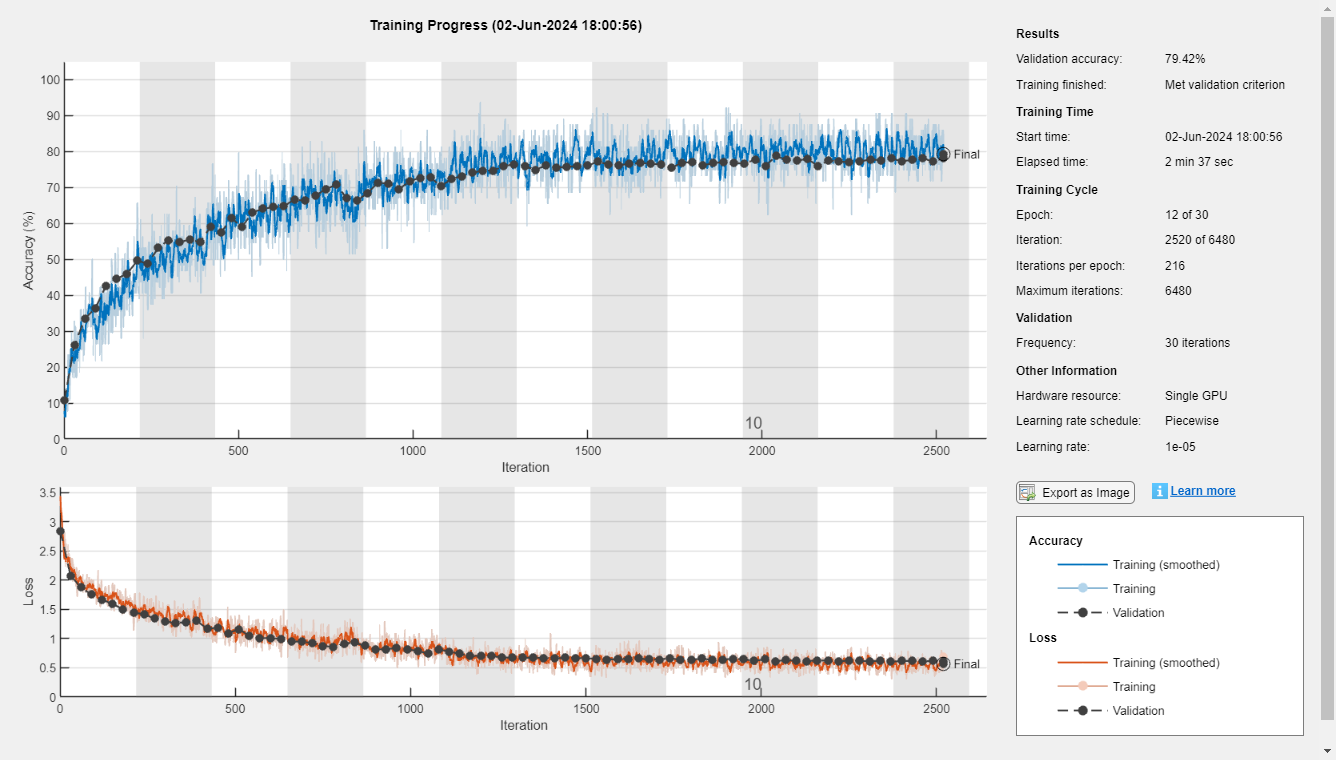

shallow_net = trainNetwork(train_data, train_labels, shallow_layers, options);

Check out the image and the accuracy of the classification.

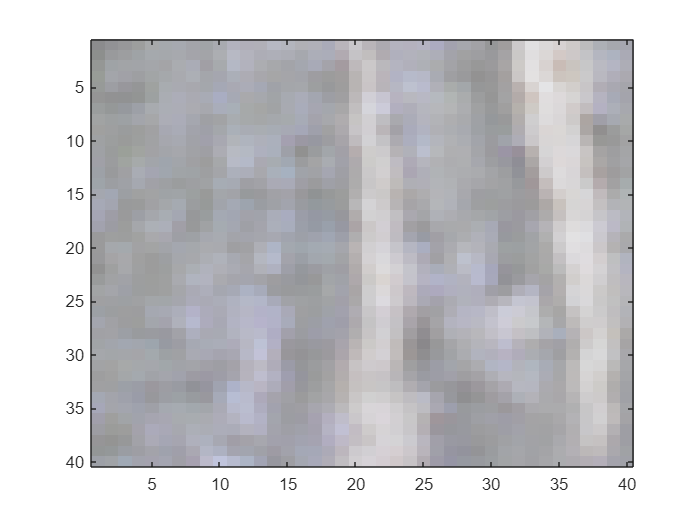

N = 1576;
img = imgs_test_data(:,:,:,N);
imagesc(img)

shallow_net.predict(img)

ans = 1×12 single row vector
    0.0008    0.0120    0.0018    0.0003    0.0001    0.9645    0.0177    0.0024    0.0001    0.0003    0.0000    0.0000


shallow_net.classify(img)

ans = categorical
     hornbeam 



prediction = classify(shallow_net, imgs_test_data);
acc = mean(prediction == imgs_test_labels);
disp(['Test set accuracy: ', num2str(acc * 100), '%']);

Test set accuracy: 71.8461%


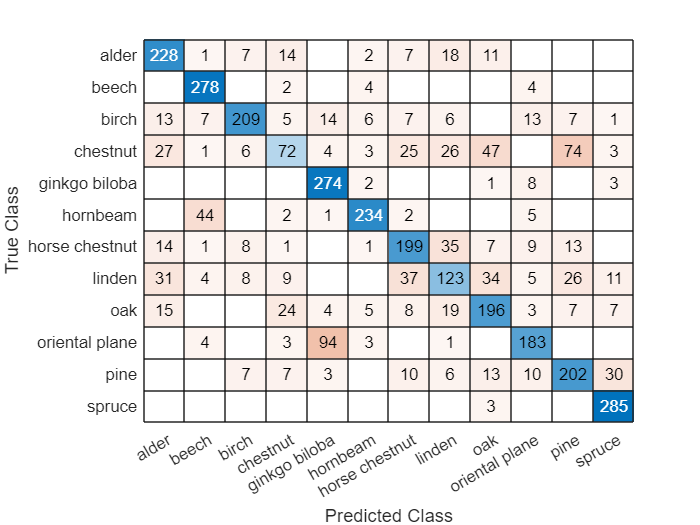


confusionchart(imgs_test_labels, prediction)

Creata a vizualisation for correctly and incorrectly classified images 

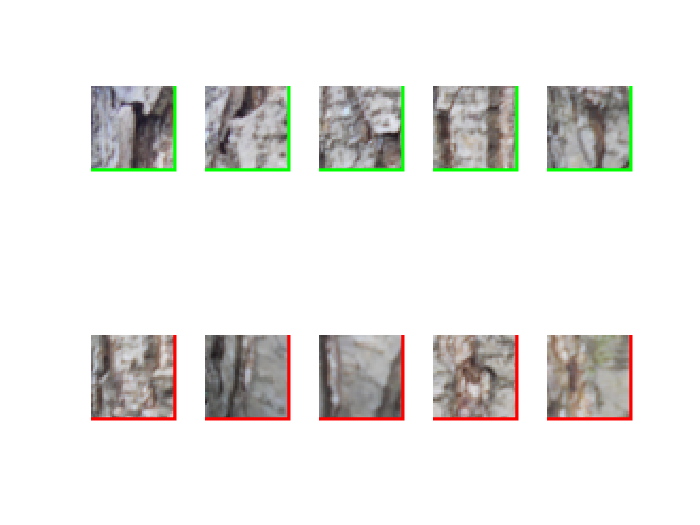

correctIndices = find(prediction == imgs_test_labels);
incorrectIndices = find(prediction ~= imgs_test_labels);

numImagesToShow = 5;

figure;
for i = 1:numCorrectImagesToShow
    subplot(2, numImagesToShow, i);
    imshow(imgs_test_data(:,:,:,correctIndices(i)));
    rectangle('Position', [0 0 40 40], 'EdgeColor', 'g', 'LineWidth', 2);
end

for i = 1:numIncorrectImagesToShow
    subplot(2, numImagesToShow, numImagesToShow + i);
    imshow(imgs_test_data(:,:,:,incorrectIndices(i)));
    rectangle('Position', [0 0 40 40], 'EdgeColor', 'r', 'LineWidth', 2);
end